# Segmenting Ripe Strawberries by Thresholding the Red and Green Color Planes

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

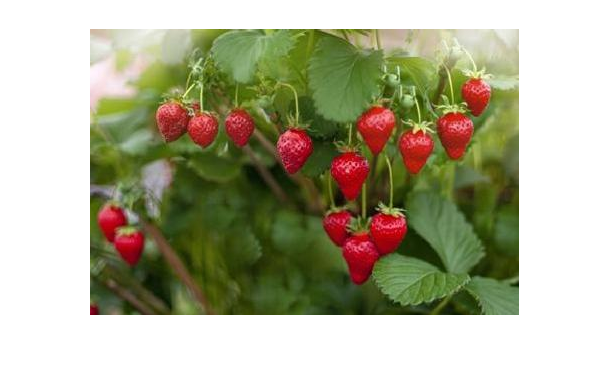

sb = imread("./images/strawberryPlant.jpg");
imshow(sb)

## Task 1

You can extract individual color planes by indexing.

`bluePlane` `=` `im``(``:,:,``3``)``;`

Or, you can extract all of them at once with `imsplit`.

`[``red``,``green``,``blue``]` `=` `imsplit``(``im``)``;`

You can display images side by side using the `"montage"` method of `imshowpair`

`imshowpair``(``I1``,``I2``,``"montage"``)`

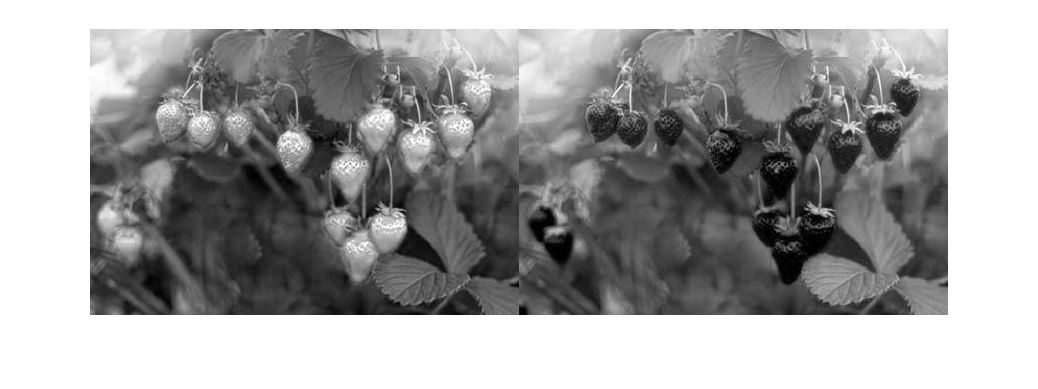

[r, g] = imsplit(sb);
imshowpair(r, g, "montage")

## Task 2

The strawberries are red, so you will first try segmentation using the red color plane. By itself, the red color plane is a grayscale image.

One way to segment a grayscale image is with the `imbinarize` function.

`BW` `=` `imbinarize``(``gs``)``;`

The output `BW` is a binary image where foreground pixels have value `1` and background pixels have value `0`.

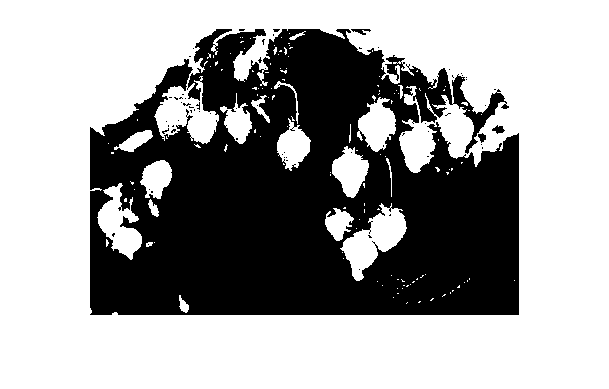

sbBW = imbinarize(r);
imshow(sbBW)

## Task 3

The segmentation using `imbinarize` included too many pixels.  

You can try setting a global threshold manually with a relational operator

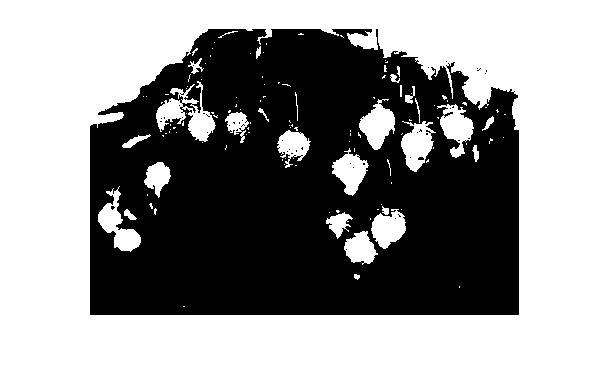

redMask = r > 150;
imshow(redMask)

## Task 4

The corners have high intensities for all of the color planes since they are bright. So, they will be hard to exclude using the red color plane.

Since red and green are the dominant colors in this image, another way to identify the strawberries is to look for pixels without much green.

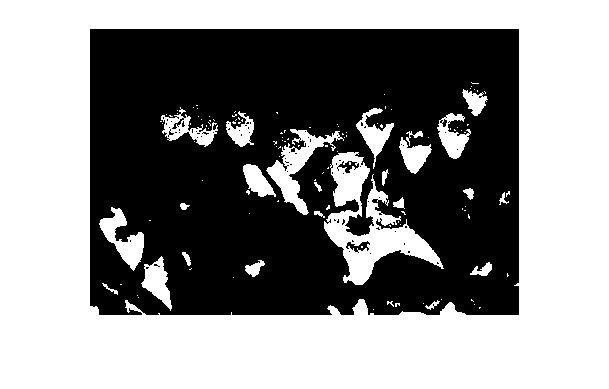

greenMask = g < 50;
imshow(greenMask)